# **demo13 of Im2mesh package**

demo13 - How to use Gmsh as mesh generator in Im2mesh package

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

**Before starting, we need to download Gmsh (**[**https://gmsh.info**](https://gmsh.info)**) and un-zip.**

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

We add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

**We need to know the location of gmesh.exe**

% for example
path_to_gmsh = 'C:\Users\Jason\Downloads\gmsh-4.13.1-Windows64\gmsh.exe';

## Get boundries from image

We have demostrate how to do this in example3 of demo01.mlx

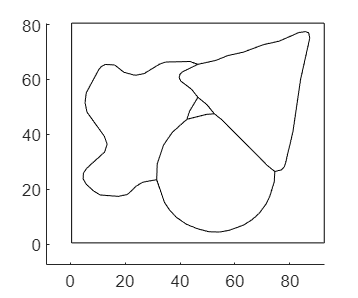

im = imread('Shape.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end

opt = [];   % reset opt
opt.tolerance = 0.3;
opt.tf_mesh = false;

bounds = im2mesh( im, opt );

% bounds is the simplified polygonal boundaries
plotBounds( bounds );

### Phase selection before meshing

Suppose we don't need the background.

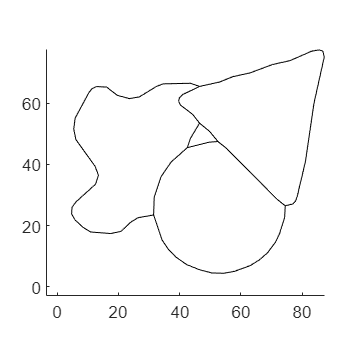

select_phase = [2 3 4];
bounds = bounds( select_phase );
plotBounds( bounds );

## Unstructured triangular mesh

### Write geo file for Gmsh

geo file is a text file that contains Gmsh’s own scripting language. It’s used to define geometry and mesh generation instructions for Gmsh.

We use function bounds2geo to generate geo file. 

% setup parameters
opt = [];   % reset
opt.sizeMin = 0.1;
opt.sizeMax = 6;
opt.algthm = 6;
opt.recombAll = 0;
opt.recombAlgthm = 3;
opt.eleOrder = 1;
opt.num_split = 0;
opt.grad_mode = 0;

path_to_geo = 'gmshTemp.geo';

bounds2geo( bounds, path_to_geo, opt );

bounds2geo Done! Check the geo file!


We will see a geo file 'gmshTemp.geo' generated in the current working folder of MATLAB.

There are many parameters for function bounds2geo. You can open bounds2geo.m to take a look at their meanings

Here is the general guideline for choosing the value of these parameters:

 1. To generate triangular mesh, you can set opt.algthm to 1-7 and set opt.recombAll to 0.

 2. To generate unstructured quadrilateral mesh, you can set opt.algthm to 8 and set opt.recombAll to 1. You can try different opt.recombAlgthm.

 3. To generate quasi-structured quadrilateral mesh, you can set opt.algthm to 11 and set opt.recombAll to 0.

 4. When opt.grad_mode is 0, you can adjust the value of opt.sizeMax to achieve better mesh quality. Typical value of opt.sizeMax is 4 to 20.

 5. When opt.grad_mode is 1, you can adjust opt.sizeAtBound, opt.sizeSlope, and opt.sizeMax to achieve better mesh quality.

### Generate mesh via Gmsh

After we got the geo file, we use the following command to send the geo file to Gmsh. Gmsh will generate a m file 'gmshTemp.m'. 

path_to_m = 'gmshTemp.m';
verbosity = 3;

str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, verbosity );
system(str);

When we run the m file, we will see a struct variable 'msh' in the workspace of MATLAB.

% run m file
run(path_to_m)
msh

msh = struct with fields:
        nbNod: 398
          POS: [398×3 double]
          MAX: [87.2400 77.4400 0]
          MIN: [4.6900 4.4500 0]
    TRIANGLES: [716×4 double]


Then, we can use function extractMsh to extract nodes and elements from the struct variable 'msh'. Function extractMsh also works for quadratic elements.

[vert,ele,tnum] = extractMsh( msh );

 382 negative area elements are fixed.


### Plot mesh

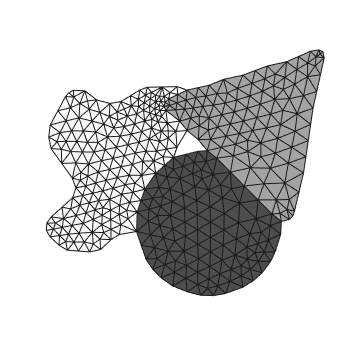

plotMeshes(vert,ele,tnum)

We can use function tricost to check the mesh quality. Function tricost is written by by Darren Engwirda.

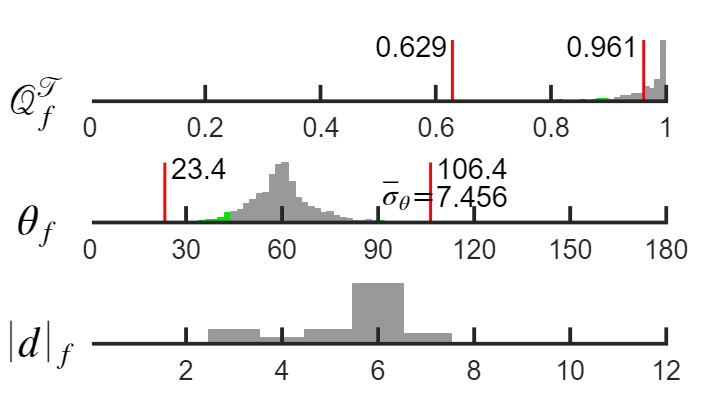

tricost( vert, ele, tnum );

## Export mesh via Gmsh

After we got the mesh, we can use Gmsh or the functions in demo03 to export it. Suppose we want to export as stl file 'gmshExport.stl'.

path_to_file = 'gmshExport.stl';
verbosity = 3;

str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_file, verbosity );
system(str);

We should be able to see a file 'gmshExport.stl' in current working folder of Matlab.

## Unstructured quadrilateral mesh

### Write geo file and generate mesh via Gmsh

We can use Gmsh to generate unstructured quadrilateral mesh by setting opt.algthm to 8 and set opt.recombAll to 1.

% setup parameters
opt = [];   % reset
opt.sizeMin = 0.1;
opt.sizeMax = 6;
opt.algthm = 8;
opt.recombAll = 1;
opt.recombAlgthm = 3;
opt.eleOrder = 1;
opt.num_split = 0;
opt.grad_mode = 0;

path_to_geo = 'gmshTemp.geo';

bounds2geo( bounds, path_to_geo, opt );

bounds2geo Done! Check the geo file!



path_to_m = 'gmshTemp.m';
verbosity = 3;
str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, verbosity );
system(str);

Gmsh will generate a m file. When we run the m file, we will see a struct variable 'msh' in the workspace of MATLAB.

% run m file
run(path_to_m)
msh

msh = struct with fields:
    nbNod: 871
      POS: [871×3 double]
      MAX: [87.2400 77.4400 0]
      MIN: [4.6900 4.4500 0]
    QUADS: [806×5 double]


Then, we can use function extractMsh to extract nodes and elements from the struct variable 'msh'. Function extractMsh also works for quadratic elements.

[vert,ele,tnum] = extractMsh( msh );

 389 negative area elements are fixed.


### Plot mesh

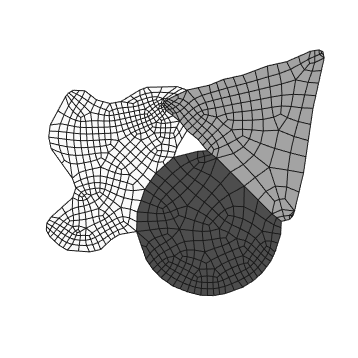

plotMeshes(vert,ele,tnum)

Awesome!

### Mesh quality

We can use function [MeshQualityQuads](https://www.mathworks.com/matlabcentral/fileexchange/33108-unstructured-quadrilateral-mesh-quality-assessment) (written by Allan Peter Engsig-Karup) to evaluate mesh quality.

[Q,theta] = MeshQualityQuads( ele(:,1:4), vert(:,1), vert(:,2) );

Mean value of Q

mean_Q = mean(Q)

mean_Q = 0.6407

Standard deviation of theta (in degree)

std_theta = std( rad2deg(theta(:)) )

std_theta = 15.1891

Plot histogram of Q

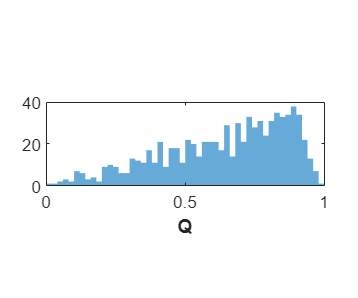

histogram( Q, 'BinWidth', 0.02, 'BinLimits', [0,1], ...
			'EdgeColor', 'none');
xlabel('Q','FontSize',10,'FontWeight','bold');
pbaspect([2 0.6 1]);

After we got the mesh, we can use Gmsh or the functions in demo03 to export it.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo